n = length(x);
opts = optimoptions('ga', 'Display', 'iter');

beq_values = [24, 21, 18, 15, 12];
Aeq = ones(1, n);

problem2_results = struct([]);

for i = 1:numel(beq_values)
    beq = beq_values(i);

    fprintf('\n========== beq = %g, sum(t) = %g ==========\n', beq, beq);

    t_opt = ga(@(t) objFun(t, classicload, classicwind, classicsun, fenshijijia), ...
               n, [], [], Aeq, beq, zeros(n,1), ones(n,1), [], 1:n, opts);
    t_opt = t_opt(:);
    J_min = objFun(t_opt, classicload, classicwind, classicsun, fenshijijia);
    fprintf('最小目标值 J = %.6g\n', J_min);
    disp('最优 t 向量：'); disp(t_opt);

    problem2_nh3load = t_opt*20.75*2;
    problem2_load = classicload*6 + problem2_nh3load;
    problem2_generate = classicwind*40 + classicsun*64;
    problem2_buy = problem2_load - problem2_generate;
    problem2_sell = problem2_buy;
    problem2_buy(problem2_buy<0) = 0;
    problem2_sell(problem2_sell>0) = 0;
    problem2_buycost = sum(problem2_buy .* fenshijijia);
    problem2_dayload = sum(problem2_load);
    problem2_daygenerate = sum(problem2_generate);
    problem2_daybuy = sum(problem2_buy);
    problem2_daysell = abs(sum(problem2_sell));
    problem2_xnyzf = (problem2_dayload-problem2_daysell-problem2_daybuy)/problem2_daygenerate;
    problem2_zydl = (problem2_daygenerate-problem2_daysell)/problem2_dayload;
    problem2_xnysw = problem2_daysell/problem2_daygenerate;
    fprintf('新能源自发自用电量占总可用发电量比例 = %.6g\n', problem2_xnyzf);
    fprintf('总用电量中绿电占比 = %.6g\n', problem2_zydl);
    fprintf('新能源上网电量比例 = %.6g\n', problem2_xnysw);

    problem2_results(i).beq = beq;
    problem2_results(i).t_opt = t_opt;
    problem2_results(i).J_min = J_min;
    problem2_results(i).nh3load = problem2_nh3load;
    problem2_results(i).load = problem2_load;
    problem2_results(i).generate = problem2_generate;
    problem2_results(i).buy = problem2_buy;
    problem2_results(i).sell = problem2_sell;
    problem2_results(i).buycost = problem2_buycost;
    problem2_results(i).dayload = problem2_dayload;
    problem2_results(i).daygenerate = problem2_daygenerate;
    problem2_results(i).daybuy = problem2_daybuy;
    problem2_results(i).daysell = problem2_daysell;
    problem2_results(i).xnyzf = problem2_xnyzf;
    problem2_results(i).zydl = problem2_zydl;
    problem2_results(i).xnysw = problem2_xnysw;
end


========== beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            6265            6265        0
    2                3            6265            6265        1
    3                4            6265            6265        2
    4                5            6265            6265        3
    5                6            6265            6265        4
    6                7            6265            6265        5
    7                8            6265            6265        6
    8                9            6265            6265        7
    9               10            6265            6265        8
   10               11            6265            6265        9
   11               12       

最小目标值 J = 6264.8


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.281556


总用电量中绿电占比 = 0.692075


新能源上网电量比例 = 0.359222



========== beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              147            6141            6196        0
    2              228            6133            6197        0
    3              304            6133            6199        1
    4              384            6133            6197        2
    5              463            6118            6197        0
    6              543            6118            6197        1
    7              620            5951            6194        0
    8              696            5951            6196        1
    9              772            5951            6192        2
   10              850            5932            6187        0
   11              928       

最小目标值 J = 5762.47


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.281556


总用电量中绿电占比 = 0.692075


新能源上网电量比例 = 0.359222



========== beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5525            6014        0
    2              295            5525            6016        1
    3              390            5525            6003        2
    4              485            5453            5990        0
    5              580            5369            5990        0
    6              675            5223            5986        0
    7              770            5223            5966        1
    8              865            5223            5965        2
    9              960            5222            5925        0
   10             1055            5208            5943        0
   11             1150       

最小目标值 J = 4785.87


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.281556


总用电量中绿电占比 = 0.692075


新能源上网电量比例 = 0.359222



========== beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4626            5593        0
    2              295            4626            5614        1
    3              390            4318            5505        0
    4              485            4318            5481        1
    5              580            4318            5480        2
    6              675            4318            5442        3
    7              770            4318            5445        4
    8              865            4318            5340        5
    9              960            4318            5297        6
   10             1055            4318            5284        7
   11             1150       

最小目标值 J = 4050.3


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.281556


总用电量中绿电占比 = 0.692075


新能源上网电量比例 = 0.359222



========== beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3594            4737        0
    2              295            3594            4612        1
    3              390            3594            4539        2
    4              485            3594            4507        3
    5              580            3594            4482        4
    6              675            3431            4461        0
    7              770            3431            4483        1
    8              865            3431            4484        2
    9              960            3431            4437        3
   10             1055            3382            4380        0
   11             1150       

最小目标值 J = 3283


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     0
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.281556


总用电量中绿电占比 = 0.692075


新能源上网电量比例 = 0.359222



function J = objFun(t, classicload, classicwind, classicsun, fenshijijia)
    t = t(:);
    problem2_nh3load = t*20.75*2;
    problem2_load = classicload*6 + problem2_nh3load;
    problem2_generate = classicwind*40 + classicsun*64;
    problem2_buy = problem2_load - problem2_generate;
    problem2_sell = problem2_buy;
    problem2_buy(problem2_buy<0) = 0;
    problem2_sell(problem2_sell>0) = 0;
    problem2_buycost = sum(problem2_buy .* fenshijijia);
    problem2_sellcost = sum(problem2_sell*377.9);
    problem2_cost =   problem2_sellcost + problem2_buycost ...
                  + 0.75*2*sum(t)*2 ...
                  + 1.5*2*1000*0.2*60000/365/30 ...
                  + 10*2*sum(t)*100 ...
                  + 10*2*sum(t)*150 ...
                  + sum(classicsun)*64*1000*0.12 ...
                  + sum(classicwind)*40*1000*0.15;
    J = problem2_cost / (sum(t)*3);
end

wind_vectors = {wind1(:), wind2(:), wind3(:), wind4(:), wind5(:), wind6(:)};
wind_names = {'wind1', 'wind2', 'wind3', 'wind4', 'wind5', 'wind6'};
sun_vectors = {sun1(:), sun2(:), sun3(:), sun4(:)};
sun_names = {'sun1', 'sun2', 'sun3', 'sun4'};

classicload = classicload(:);
fenshijijia = fenshijijia(:);
n = numel(wind_vectors{1});


opts = optimoptions('ga', 'Display', 'iter');

% 分别在以下约束下运行优化：sum(t) = beq
beq_values = [24, 21, 18, 15, 12];
Aeq = ones(1, n);

problem2_results = struct([]);
result_idx = 0;

for wind_idx = 1:numel(wind_vectors)
    wind = wind_vectors{wind_idx};
    wind_name = wind_names{wind_idx};

    for sun_idx = 1:numel(sun_vectors)
        sun = sun_vectors{sun_idx};
        sun_name = sun_names{sun_idx};

        fprintf('\n\n==================== 情况 %02d：%s + %s ====================\n', ...
                (wind_idx - 1)*numel(sun_vectors) + sun_idx, wind_name, sun_name);

        for beq_idx = 1:numel(beq_values)
            beq = beq_values(beq_idx);

            fprintf('\n========== %s + %s, beq = %g, sum(t) = %g ==========\n', ...
                    wind_name, sun_name, beq, beq);

            t_opt = ga(@(t) objFun(t, classicload, wind, sun, fenshijijia), ...
                       n, [], [], Aeq, beq, zeros(n,1), ones(n,1), [], 1:n, opts);
            t_opt = t_opt(:);
            J_min = objFun(t_opt, classicload, wind, sun, fenshijijia);
            fprintf('最小目标值 J = %.6g\n', J_min);
            disp('最优 t 向量：'); disp(t_opt);

            metrics = calcProblem2Metrics(t_opt, classicload, wind, sun, fenshijijia, ...
                                          problem2_dayload, problem2_daysell, ...
                                          problem2_daybuy, problem2_daygenerate);

            problem2_nh3load = metrics.nh3load;
            problem2_load = metrics.load;
            problem2_generate = metrics.generate;
            problem2_buy = metrics.buy;
            problem2_sell = metrics.sell;
            problem2_buycost = metrics.buycost;
            problem2_dayload = metrics.dayload;
            problem2_daygenerate = metrics.daygenerate;
            problem2_daybuy = metrics.daybuy;
            problem2_daysell = metrics.daysell;
            problem2_xnyzf = metrics.xnyzf;
            problem2_zydl = metrics.zydl;
            problem2_xnysw = metrics.xnysw;

            fprintf('新能源自发自用电量占总可用发电量比例 = %.6g\n', problem2_xnyzf);
            fprintf('总用电量中绿电占比 = %.6g\n', problem2_zydl);
            fprintf('新能源上网电量比例 = %.6g\n', problem2_xnysw);

            result_idx = result_idx + 1;
            problem2_results(result_idx).case_idx = result_idx;
            problem2_results(result_idx).wind_idx = wind_idx;
            problem2_results(result_idx).wind_name = wind_name;
            problem2_results(result_idx).sun_idx = sun_idx;
            problem2_results(result_idx).sun_name = sun_name;
            problem2_results(result_idx).beq = beq;
            problem2_results(result_idx).t_opt = t_opt;
            problem2_results(result_idx).J_min = J_min;
            problem2_results(result_idx).nh3load = problem2_nh3load;
            problem2_results(result_idx).load = problem2_load;
            problem2_results(result_idx).generate = problem2_generate;
            problem2_results(result_idx).buy = problem2_buy;
            problem2_results(result_idx).sell = problem2_sell;
            problem2_results(result_idx).buycost = problem2_buycost;
            problem2_results(result_idx).dayload = problem2_dayload;
            problem2_results(result_idx).daygenerate = problem2_daygenerate;
            problem2_results(result_idx).daybuy = problem2_daybuy;
            problem2_results(result_idx).daysell = problem2_daysell;
            problem2_results(result_idx).xnyzf = problem2_xnyzf;
            problem2_results(result_idx).zydl = problem2_zydl;
            problem2_results(result_idx).xnysw = problem2_xnysw;
        end
    end
end



==================== 情况 01：wind1 + sun1 ====================



========== wind1 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            5430            5430        0
    2                3            5430            5430        1
    3                4            5430            5430        2
    4                5            5430            5430        3
    5                6            5430            5430        4
    6                7            5430            5430        5
    7                8            5430            5430        6
    8                9            5430            5430        7
    9               10            5430            5430        8
   10               11            5430            5430        9
   11               12       

最小目标值 J = 5430.08


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.42831


新能源上网电量比例 = 0



========== wind1 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              152            5221            5255        0
    2              236            5221            5255        1
    3              317            5221            5254        2
    4              402            5221            5255        3
    5              482            5221            5256        4
    6              565            5221            5254        5
    7              648            5221            5255        6
    8              729            5074            5254        0
    9              805            5074            5255        1
   10              886            5074            5253        2
   11              966       

最小目标值 J = 4993.72


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.644709


总用电量中绿电占比 = 0.592816


新能源上网电量比例 = 0.177646



========== wind1 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              196            4454            4971        0
    2              290            4454            4954        1
    3              384            4454            4939        2
    4              478            4371            4902        0
    5              573            4352            4889        0
    6              668            4352            4892        1
    7              763            4352            4888        2
    8              858            4352            4883        3
    9              953            4352            4899        4
   10             1048            4352            4893        5
   11             1143       

最小目标值 J = 3905.36


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.423112


总用电量中绿电占比 = 0.581448


新能源上网电量比例 = 0.288444



========== wind1 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3224            4320        0
    2              295            3224            4265        1
    3              390            3224            4166        2
    4              485            3224            4072        3
    5              580            3224            4072        0
    6              675            3224            4127        1
    7              770            3224            4122        2
    8              865            3224            4086        3
    9              960            3224            4047        4
   10             1055            3203            4039        0
   11             1150       

最小目标值 J = 3096.74


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.399934


总用电量中绿电占比 = 0.660142


新能源上网电量比例 = 0.300033



========== wind1 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            2291            3374        0
    2              295            2291            3318        1
    3              390            2291            3300        2
    4              485            2247            3235        0
    5              580            2247            3149        1
    6              675            2247            3170        2
    7              770            2247            3146        3
    8              865            2247            3136        4
    9              960            2247            3095        5
   10             1055            2247            2954        6
   11             1150       

最小目标值 J = 2147.11


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.181494


总用电量中绿电占比 = 0.65866


新能源上网电量比例 = 0.409253




==================== 情况 02：wind1 + sun2 ====================



========== wind1 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            6803            6803        0
    2                3            6803            6803        1
    3                4            6803            6803        2
    4                5            6803            6803        3
    5                6            6803            6803        4
    6                7            6803            6803        5
    7                8            6803            6803        6
    8                9            6803            6803        7
    9               10            6803            6803        8
   10               11            6803            6803        9
   11               12       

最小目标值 J = 6802.67


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = -0.145379


总用电量中绿电占比 = 0.582599


新能源上网电量比例 = 0.572689



========== wind1 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              154            6672            6783        0
    2              238            6611            6783        0
    3              316            6611            6786        1
    4              398            6611            6783        2
    5              478            6611            6782        3
    6              560            6601            6774        0
    7              638            6586            6778        0
    8              719            6527            6778        0
    9              800            6527            6781        1
   10              881            6527            6775        2
   11              965       

最小目标值 J = 6427.25


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.970389


总用电量中绿电占比 = 0.469144


新能源上网电量比例 = 0.0148055



========== wind1 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              195            6176            6635        0
    2              287            6176            6614        1
    3              382            6105            6593        0
    4              477            5946            6576        0
    5              572            5946            6609        1
    6              667            5946            6612        2
    7              762            5946            6601        3
    8              857            5946            6610        4
    9              952            5946            6594        5
   10             1047            5946            6595        6
   11             1142       

最小目标值 J = 5620.76


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.754278


总用电量中绿电占比 = 0.473472


新能源上网电量比例 = 0.122861



========== wind1 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5667            6385        0
    2              295            5667            6353        1
    3              390            5667            6330        2
    4              485            5152            6275        0
    5              580            5152            6208        1
    6              675            5152            6152        2
    7              770            5152            6091        3
    8              865            5152            6042        4
    9              960            5152            6031        5
   10             1055            5152            6049        6
   11             1150       

最小目标值 J = 5004.27


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.649454


总用电量中绿电占比 = 0.513799


新能源上网电量比例 = 0.175273



========== wind1 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4591            5611        0
    2              295            4419            5533        0
    3              390            4419            5482        1
    4              485            4419            5413        2
    5              580            4410            5366        0
    6              675            4410            5338        1
    7              770            4410            5382        2
    8              865            4410            5366        3
    9              960            4410            5298        4
   10             1055            4370            5329        0
   11             1150       

最小目标值 J = 4120


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.436418


总用电量中绿电占比 = 0.528974


新能源上网电量比例 = 0.281791




==================== 情况 03：wind1 + sun3 ====================



========== wind1 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8163            8163        0
    2                3            8163            8163        1
    3                4            8163            8163        2
    4                5            8163            8163        3
    5                6            8163            8163        4
    6                7            8163            8163        5
    7                8            8163            8163        6
    8                9            8163            8163        7
    9               10            8163            8163        8
   10               11            8163            8163        9
   11               12       

最小目标值 J = 8163.38


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.176858


总用电量中绿电占比 = 0.529961


新能源上网电量比例 = 0.411571



========== wind1 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              155            7988            8283        0
    2              236            7988            8291        1
    3              317            7975            8286        0
    4              402            7904            8279        0
    5              483            7904            8281        1
    6              569            7888            8267        0
    7              650            7888            8270        1
    8              736            7888            8272        2
    9              819            7888            8275        3
   10              902            7886            8271        0
   11              984       

最小目标值 J = 7741.83


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.319332


新能源上网电量比例 = 0



========== wind1 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              199            7695            8189        0
    2              294            7695            8174        1
    3              389            7611            8170        0
    4              484            7557            8158        0
    5              579            7477            8180        0
    6              674            7477            8153        1
    7              769            7477            8126        2
    8              864            7477            8114        3
    9              959            7477            8129        4
   10             1054            7477            8126        5
   11             1149       

最小目标值 J = 7181.32


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.79225


总用电量中绿电占比 = 0.324378


新能源上网电量比例 = 0.103875



========== wind1 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7158            7962        0
    2              295            7158            7932        1
    3              390            6877            7858        0
    4              485            6707            7803        0
    5              580            6707            7789        1
    6              675            6707            7745        2
    7              770            6707            7710        3
    8              865            6707            7698        4
    9              960            6707            7635        5
   10             1055            6707            7628        6
   11             1150       

最小目标值 J = 6563.24


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     0
     1
     0
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.583325


总用电量中绿电占比 = 0.330736


新能源上网电量比例 = 0.208337



========== wind1 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6201            7562        0
    2              295            6201            7480        1
    3              390            6201            7445        2
    4              485            6201            7424        3
    5              580            6201            7415        4
    6              675            6201            7448        5
    7              770            6201            7430        6
    8              865            6201            7426        7
    9              960            6201            7349        8
   10             1055            6201            7384        9
   11             1150       

最小目标值 J = 5801.58


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.446887


总用电量中绿电占比 = 0.35731


新能源上网电量比例 = 0.276557




==================== 情况 04：wind1 + sun4 ====================



========== wind1 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8712            8712        0
    2                3            8712            8712        1
    3                4            8712            8712        2
    4                5            8712            8712        3
    5                6            8712            8712        4
    6                7            8712            8712        5
    7                8            8712            8712        6
    8                9            8712            8712        7
    9               10            8712            8712        8
   10               11            8712            8712        9
   11               12       

最小目标值 J = 8711.89


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.261422


总用电量中绿电占比 = 0.380924


新能源上网电量比例 = 0.369289



========== wind1 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              153            8434            8874        0
    2              237            8434            8892        1
    3              318            8385            8891        0
    4              401            8385            8885        1
    5              479            8385            8885        2
    6              562            8385            8883        3
    7              644            8385            8876        4
    8              727            8385            8877        5
    9              812            8385            8871        6
   10              894            8385            8857        7
   11              972       

最小目标值 J = 8245.16


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.258161


新能源上网电量比例 = 0



========== wind1 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7904            8885        0
    2              295            7901            8816        0
    3              390            7901            8796        1
    4              485            7740            8741        0
    5              580            7740            8655        1
    6              675            7740            8681        2
    7              770            7740            8667        3
    8              865            7740            8692        4
    9              960            7740            8666        5
   10             1055            7740            8637        6
   11             1150       

最小目标值 J = 7616.62


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.877437


总用电量中绿电占比 = 0.274706


新能源上网电量比例 = 0.0612814



========== wind1 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7644            8575        0
    2              295            7644            8482        1
    3              390            7644            8470        2
    4              485            7607            8476        0
    5              580            7607            8472        1
    6              675            7607            8429        2
    7              770            7592            8420        0
    8              865            7592            8405        1
    9              960            7592            8439        2
   10             1055            7280            8354        0
   11             1150       

最小目标值 J = 7071.69


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.760691


总用电量中绿电占比 = 0.297333


新能源上网电量比例 = 0.119654



========== wind1 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6900            8397        0
    2              295            6900            8287        1
    3              390            6900            8190        2
    4              485            6900            8066        3
    5              580            6900            8064        4
    6              675            6622            8087        0
    7              770            6622            8052        1
    8              865            6622            8094        2
    9              960            6622            8086        3
   10             1055            6622            8075        4
   11             1150       

最小目标值 J = 6362.57


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.494243


总用电量中绿电占比 = 0.298319


新能源上网电量比例 = 0.252878




==================== 情况 05：wind2 + sun1 ====================



========== wind2 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            5836            5836        0
    2                3            5836            5836        1
    3                4            5836            5836        2
    4                5            5836            5836        3
    5                6            5836            5836        4
    6                7            5836            5836        5
    7                8            5836            5836        6
    8                9            5836            5836        7
    9               10            5836            5836        8
   10               11            5836            5836        9
   11               12       

最小目标值 J = 5835.93


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.447703


总用电量中绿电占比 = 0.353432


新能源上网电量比例 = 0.276148



========== wind2 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              155            5641            5711        0
    2              239            5629            5711        0
    3              320            5629            5711        1
    4              405            5629            5708        2
    5              486            5629            5711        3
    6              567            5629            5712        4
    7              642            5545            5709        0
    8              726            5540            5708        0
    9              808            5540            5706        1
   10              891            5513            5701        0
   11              968       

最小目标值 J = 5451.5


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.727997


总用电量中绿电占比 = 0.538735


新能源上网电量比例 = 0.136002



========== wind2 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            4920            5458        0
    2              293            4920            5443        1
    3              388            4920            5424        2
    4              483            4880            5423        0
    5              578            4880            5399        1
    6              673            4676            5399        0
    7              768            4676            5400        1
    8              863            4653            5404        0
    9              958            4653            5414        1
   10             1053            4653            5392        2
   11             1148       

最小目标值 J = 4521.03


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.476397


总用电量中绿电占比 = 0.521767


新能源上网电量比例 = 0.261801



========== wind2 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4118            5031        0
    2              295            4118            4984        1
    3              390            3854            4962        0
    4              485            3854            4908        1
    5              580            3854            4923        2
    6              675            3854            4892        3
    7              770            3854            4932        4
    8              865            3854            4882        5
    9              960            3854            4805        6
   10             1055            3854            4817        7
   11             1150       

最小目标值 J = 3613.35


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.383976


总用电量中绿电占比 = 0.564495


新能源上网电量比例 = 0.308012



========== wind2 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            2971            3982        0
    2              295            2971            3946        1
    3              390            2971            3977        2
    4              485            2956            3904        0
    5              580            2956            3875        1
    6              675            2895            3864        0
    7              770            2895            3864        1
    8              865            2895            3817        2
    9              960            2895            3775        3
   10             1055            2830            3705        0
   11             1150       

最小目标值 J = 2803.28


最优 t 向量：
     1
     0
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.26368


总用电量中绿电占比 = 0.609352


新能源上网电量比例 = 0.36816




==================== 情况 06：wind2 + sun2 ====================



========== wind2 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            7366            7366        0
    2                3            7366            7366        1
    3                4            7366            7366        2
    4                5            7366            7366        3
    5                6            7366            7366        4
    6                7            7366            7366        5
    7                8            7366            7366        6
    8                9            7366            7366        7
    9               10            7366            7366        8
   10               11            7366            7366        9
   11               12       

最小目标值 J = 7365.76


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.000338137


总用电量中绿电占比 = 0.589854


新能源上网电量比例 = 0.499831



========== wind2 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              154            7097            7391        0
    2              237            7097            7396        1
    3              318            7097            7393        2
    4              400            7097            7390        3
    5              481            7097            7400        4
    6              563            7097            7388        5
    7              644            7097            7390        6
    8              723            7097            7387        7
    9              802            7097            7386        8
   10              882            7097            7394        9
   11              965       

最小目标值 J = 7096.58


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.378855


新能源上网电量比例 = 0



========== wind2 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6650            7280        0
    2              295            6650            7278        1
    3              390            6636            7263        0
    4              485            6636            7226        1
    5              580            6633            7222        0
    6              675            6299            7191        0
    7              770            6299            7210        1
    8              865            6299            7197        2
    9              960            6299            7189        3
   10             1055            6299            7174        4
   11             1150       

最小目标值 J = 6226.48


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.839357


总用电量中绿电占比 = 0.394958


新能源上网电量比例 = 0.0803214



========== wind2 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6411            7136        0
    2              295            6411            7113        1
    3              390            6411            7085        2
    4              485            5853            7000        0
    5              580            5853            6969        1
    6              675            5853            6972        2
    7              770            5853            6917        3
    8              865            5853            6907        4
    9              960            5853            6881        5
   10             1055            5853            6809        6
   11             1150       

最小目标值 J = 5619.18


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.726405


总用电量中绿电占比 = 0.427844


新能源上网电量比例 = 0.136797



========== wind2 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5581            6492        0
    2              295            5367            6383        0
    3              390            5216            6351        0
    4              485            5216            6218        1
    5              580            5216            6266        2
    6              675            5216            6287        3
    7              770            5216            6351        4
    8              865            5216            6286        5
    9              960            5216            6201        6
   10             1055            5216            6188        7
   11             1150       

最小目标值 J = 4838.56


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.5683


总用电量中绿电占比 = 0.459486


新能源上网电量比例 = 0.21585




==================== 情况 07：wind2 + sun3 ====================



========== wind2 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8770            8770        0
    2                3            8770            8770        1
    3                4            8770            8770        2
    4                5            8770            8770        3
    5                6            8770            8770        4
    6                7            8770            8770        5
    7                8            8770            8770        6
    8                9            8770            8770        7
    9               10            8770            8770        8
   10               11            8770            8770        9
   11               12       

最小目标值 J = 8770.4


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.308055


总用电量中绿电占比 = 0.468635


新能源上网电量比例 = 0.345972



========== wind2 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              154            8512            8925        0
    2              237            8449            8906        0
    3              319            8449            8924        1
    4              397            8449            8941        2
    5              480            8449            8945        3
    6              562            8449            8936        4
    7              643            8449            8932        5
    8              724            8449            8932        6
    9              805            8449            8932        7
   10              890            8449            8928        8
   11              973       

最小目标值 J = 8372.75


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.221993


新能源上网电量比例 = 0



========== wind2 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            8307            8964        0
    2              292            8307            8913        1
    3              386            8307            8880        2
    4              480            8275            8876        0
    5              574            8234            8866        0
    6              669            8234            8861        1
    7              764            8038            8772        0
    8              859            8038            8832        1
    9              954            8038            8816        2
   10             1049            8038            8796        3
   11             1144       

最小目标值 J = 7779.02


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.780635


总用电量中绿电占比 = 0.22404


新能源上网电量比例 = 0.109683



========== wind2 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7778            8728        0
    2              295            7778            8640        1
    3              390            7778            8685        2
    4              485            7706            8603        0
    5              580            7575            8600        0
    6              675            7575            8566        1
    7              770            7407            8501        0
    8              865            7407            8439        1
    9              960            7407            8503        2
   10             1055            7407            8505        3
   11             1150       

最小目标值 J = 7306.04


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.630169


总用电量中绿电占比 = 0.236723


新能源上网电量比例 = 0.184915



========== wind2 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7467            8567        0
    2              295            7462            8513        0
    3              390            7462            8487        0
    4              485            7430            8495        0
    5              580            7319            8380        0
    6              675            7319            8387        0
    7              770            7319            8418        1
    8              865            7319            8373        2
    9              960            7319            8399        3
   10             1055            7319            8362        4
   11             1150       

最小目标值 J = 6687.27


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.303033


总用电量中绿电占比 = 0.223699


新能源上网电量比例 = 0.348483




==================== 情况 08：wind2 + sun4 ====================



========== wind2 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            9319            9319        0
    2                3            9319            9319        1
    3                4            9319            9319        2
    4                5            9319            9319        3
    5                6            9319            9319        4
    6                7            9319            9319        5
    7                8            9319            9319        6
    8                9            9319            9319        7
    9               10            9319            9319        8
   10               11            9319            9319        9
   11               12       

最小目标值 J = 9318.91


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.206439


总用电量中绿电占比 = 0.253267


新能源上网电量比例 = 0.396781



========== wind2 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              157            8886            9499        0
    2              240            8886            9540        1
    3              325            8886            9536        2
    4              405            8886            9511        3
    5              486            8886            9538        4
    6              564            8886            9544        5
    7              645            8886            9541        6
    8              727            8886            9523        7
    9              810            8886            9552        8
   10              890            8886            9533        9
   11              973       

最小目标值 J = 8886.32


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.160822


新能源上网电量比例 = 0



========== wind2 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            8683            9642        0
    2              295            8683            9617        1
    3              390            8683            9515        2
    4              485            8683            9483        3
    5              580            8683            9459        4
    6              675            8653            9424        0
    7              770            8653            9426        1
    8              865            8653            9445        2
    9              960            8653            9429        0
   10             1055            8653            9442        1
   11             1150       

最小目标值 J = 8377.91


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.895071


总用电量中绿电占比 = 0.172736


新能源上网电量比例 = 0.0524643



========== wind2 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            8539            9412        0
    2              295            8539            9378        1
    3              390            8452            9333        0
    4              485            8330            9250        0
    5              580            8330            9200        1
    6              675            8168            9177        0
    7              770            8168            9183        1
    8              865            8168            9220        2
    9              960            8168            9161        3
   10             1055            8168            9108        4
   11             1150       

最小目标值 J = 7780.55


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.687798


总用电量中绿电占比 = 0.177556


新能源上网电量比例 = 0.156101



========== wind2 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7464            9157        0
    2              295            7464            9019        1
    3              390            7464            8965        2
    4              485            7464            8918        3
    5              580            7464            8957        4
    6              675            7464            8938        5
    7              770            7464            8950        6
    8              865            7464            8947        7
    9              960            7464            8911        8
   10             1055            7464            8914        9
   11             1150       

最小目标值 J = 7216.48


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.558556


总用电量中绿电占比 = 0.193837


新能源上网电量比例 = 0.220722




==================== 情况 09：wind3 + sun1 ====================



========== wind3 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            5282            5282        0
    2                3            5282            5282        1
    3                4            5282            5282        2
    4                5            5282            5282        3
    5                6            5282            5282        4
    6                7            5282            5282        5
    7                8            5282            5282        6
    8                9            5282            5282        7
    9               10            5282            5282        8
   10               11            5282            5282        9
   11               12       

最小目标值 J = 5282.33


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.543231


总用电量中绿电占比 = 0.2347


新能源上网电量比例 = 0.228385



========== wind3 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              167            5028            5077        0
    2              252            5028            5079        1
    3              332            5028            5080        2
    4              418            5028            5077        3
    5              501            5028            5079        4
    6              587            5028            5078        5
    7              669            5028            5077        6
    8              751            4947            5077        0
    9              834            4906            5075        0
   10              919            4906            5073        1
   11             1001       

最小目标值 J = 4890.48


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.676328


总用电量中绿电占比 = 0.619343


新能源上网电量比例 = 0.161836



========== wind3 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            4340            4751        0
    2              293            4340            4729        1
    3              388            4134            4724        0
    4              483            4134            4719        1
    5              578            4022            4686        0
    6              673            4022            4655        1
    7              768            4022            4643        2
    8              863            4022            4655        3
    9              958            4022            4668        4
   10             1053            3845            4661        0
   11             1148       

最小目标值 J = 3845.29


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.426464


总用电量中绿电占比 = 0.597413


新能源上网电量比例 = 0.286768



========== wind3 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3406            4168        0
    2              295            3406            4162        1
    3              390            3406            4108        2
    4              485            3209            4064        0
    5              580            3209            4033        1
    6              675            3209            4029        2
    7              770            3209            4009        3
    8              865            3209            3996        4
    9              960            3209            3916        5
   10             1055            3209            3924        6
   11             1150       

最小目标值 J = 3032.36


最优 t 向量：
     0
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     0
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.382649


总用电量中绿电占比 = 0.668318


新能源上网电量比例 = 0.308675



========== wind3 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            2189            3062        0
    2              295            2163            2997        0
    3              390            2163            3033        1
    4              485            2163            3004        2
    5              580            2163            2913        3
    6              675            2163            2955        4
    7              770            2152            2928        0
    8              865            2122            2919        0
    9              960            2122            2869        1
   10             1055            2122            2887        2
   11             1150       

最小目标值 J = 2036.09


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     0
     0
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.25726


总用电量中绿电占比 = 0.71845


新能源上网电量比例 = 0.37137




==================== 情况 10：wind3 + sun2 ====================



========== wind3 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            6664            6664        0
    2                3            6664            6664        1
    3                4            6664            6664        2
    4                5            6664            6664        3
    5                6            6664            6664        4
    6                7            6664            6664        5
    7                8            6664            6664        6
    8                9            6664            6664        7
    9               10            6664            6664        8
   10               11            6664            6664        9
   11               12       

最小目标值 J = 6664.22


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = -0.140941


总用电量中绿电占比 = 0.60029


新能源上网电量比例 = 0.570471



========== wind3 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              163            6447            6605        0
    2              244            6381            6599        0
    3              326            6381            6601        1
    4              410            6381            6597        2
    5              491            6359            6603        0
    6              579            6359            6595        1
    7              661            6359            6596        2
    8              740            6359            6601        3
    9              820            6359            6602        4
   10              905            6359            6599        5
   11              983       

最小目标值 J = 6358.88


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.98573


总用电量中绿电占比 = 0.49072


新能源上网电量比例 = 0.00713487



========== wind3 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              196            5851            6416        0
    2              290            5489            6393        0
    3              385            5489            6368        1
    4              480            5489            6360        2
    5              575            5489            6336        3
    6              670            5489            6326        4
    7              765            5489            6305        5
    8              860            5489            6311        6
    9              955            5489            6321        7
   10             1050            5489            6341        8
   11             1145       

最小目标值 J = 5489.08


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.756674


总用电量中绿电占比 = 0.492092


新能源上网电量比例 = 0.121663



========== wind3 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5338            6089        0
    2              295            5338            6073        1
    3              390            5015            6053        0
    4              485            5015            5982        1
    5              580            5015            5965        2
    6              675            4999            5939        0
    7              770            4999            5956        1
    8              865            4999            5902        2
    9              960            4999            5874        3
   10             1055            4999            5847        4
   11             1150       

最小目标值 J = 4717.33


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.660074


总用电量中绿电占比 = 0.53671


新能源上网电量比例 = 0.169963



========== wind3 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4630            5338        0
    2              295            4539            5330        0
    3              390            4539            5324        1
    4              485            4539            5341        2
    5              580            4466            5302        0
    6              675            4466            5257        1
    7              770            4466            5274        2
    8              865            4466            5244        3
    9              960            4466            5243        4
   10             1055            4466            5241        5
   11             1150       

最小目标值 J = 4021.94


最优 t 向量：
     1
     0
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.551618


总用电量中绿电占比 = 0.593059


新能源上网电量比例 = 0.224191




==================== 情况 11：wind3 + sun3 ====================



========== wind3 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8047            8047        0
    2                3            8047            8047        1
    3                4            8047            8047        2
    4                5            8047            8047        3
    5                6            8047            8047        4
    6                7            8047            8047        5
    7                8            8047            8047        6
    8                9            8047            8047        7
    9               10            8047            8047        8
   10               11            8047            8047        9
   11               12       

最小目标值 J = 8046.89


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.29469


总用电量中绿电占比 = 0.605125


新能源上网电量比例 = 0.352655



========== wind3 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              151            7703            8131        0
    2              233            7703            8136        1
    3              312            7703            8133        2
    4              391            7703            8122        3
    5              478            7703            8117        4
    6              558            7703            8112        5
    7              640            7703            8127        6
    8              721            7703            8129        7
    9              803            7703            8122        8
   10              882            7703            8133        9
   11              965       

最小目标值 J = 7703.46


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.337384


新能源上网电量比例 = 0



========== wind3 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            7373            8021        0
    2              292            7373            7981        1
    3              387            7373            7945        2
    4              482            7373            7915        3
    5              577            7373            7896        4
    6              672            7373            7931        5
    7              767            7337            7916        0
    8              862            7337            7925        1
    9              957            7321            7927        0
   10             1052            7287            7914        0
   11             1147       

最小目标值 J = 7032.14


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.72447


总用电量中绿电占比 = 0.329755


新能源上网电量比例 = 0.137765



========== wind3 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6880            7726        0
    2              295            6732            7654        0
    3              390            6732            7628        1
    4              485            6732            7655        2
    5              580            6732            7606        3
    6              675            6726            7558        0
    7              770            6545            7486        0
    8              865            6545            7460        1
    9              960            6545            7469        2
   10             1055            6485            7450        0
   11             1150       

最小目标值 J = 6483.97


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.601234


总用电量中绿电占比 = 0.353385


新能源上网电量比例 = 0.199383



========== wind3 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6305            7350        0
    2              295            6305            7320        1
    3              390            6305            7333        2
    4              485            6305            7269        3
    5              580            6023            7209        0
    6              675            6023            7172        1
    7              770            6023            7190        2
    8              865            6023            7162        3
    9              960            6023            7165        4
   10             1055            6023            7139        5
   11             1150       

最小目标值 J = 5760.87


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.340109


总用电量中绿电占比 = 0.34965


新能源上网电量比例 = 0.329946




==================== 情况 12：wind3 + sun4 ====================



========== wind3 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8595            8595        0
    2                3            8595            8595        1
    3                4            8595            8595        2
    4                5            8595            8595        3
    5                6            8595            8595        4
    6                7            8595            8595        5
    7                8            8595            8595        6
    8                9            8595            8595        7
    9               10            8595            8595        8
   10               11            8595            8595        9
   11               12       

最小目标值 J = 8595.4


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.187509


总用电量中绿电占比 = 0.378876


新能源上网电量比例 = 0.406245



========== wind3 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              154            8371            8761        0
    2              236            8371            8756        1
    3              319            8229            8749        0
    4              403            8229            8731        1
    5              486            8229            8747        2
    6              571            8229            8738        3
    7              654            8229            8728        4
    8              737            8229            8741        5
    9              818            8229            8732        6
   10              901            8229            8726        7
   11              986       

最小目标值 J = 8149.21


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.276213


新能源上网电量比例 = 0



========== wind3 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            7804            8592        0
    2              293            7804            8567        1
    3              388            7804            8583        2
    4              483            7804            8515        3
    5              578            7804            8559        4
    6              673            7804            8577        5
    7              768            7804            8593        6
    8              863            7804            8573        7
    9              958            7804            8534        8
   10             1053            7804            8607        9
   11             1148       

最小目标值 J = 7591.77


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     0
     1
     1
     1
     0
     1
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.847636


总用电量中绿电占比 = 0.289249


新能源上网电量比例 = 0.076182



========== wind3 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7545            8417        0
    2              295            7545            8342        1
    3              390            7545            8326        2
    4              485            7495            8264        0
    5              580            7495            8277        1
    6              675            7495            8195        2
    7              770            7417            8174        0
    8              865            7257            8179        0
    9              960            7257            8207        1
   10             1055            7257            8222        2
   11             1150       

最小目标值 J = 6985.81


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.662601


总用电量中绿电占比 = 0.300401


新能源上网电量比例 = 0.168699



========== wind3 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7163            8210        0
    2              295            7163            8122        1
    3              390            7085            8109        0
    4              485            7069            8061        0
    5              580            6842            8017        0
    6              675            6842            7942        1
    7              770            6636            7965        0
    8              865            6636            7943        1
    9              960            6636            7857        2
   10             1055            6627            7907        0
   11             1150       

最小目标值 J = 6386.23


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.460377


总用电量中绿电占比 = 0.311945


新能源上网电量比例 = 0.269812




==================== 情况 13：wind4 + sun1 ====================



========== wind4 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            4936            4936        0
    2                3            4936            4936        1
    3                4            4936            4936        2
    4                5            4936            4936        3
    5                6            4936            4936        4
    6                7            4936            4936        5
    7                8            4936            4936        6
    8                9            4936            4936        7
    9               10            4936            4936        8
   10               11            4936            4936        9
   11               12       

最小目标值 J = 4935.96


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.276067


总用电量中绿电占比 = 0.333314


新能源上网电量比例 = 0.361967



========== wind4 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              151            4656            4683        0
    2              232            4656            4684        1
    3              316            4656            4683        2
    4              399            4656            4684        3
    5              482            4656            4683        4
    6              567            4656            4684        5
    7              650            4656            4683        6
    8              733            4568            4682        0
    9              813            4564            4680        0
   10              892            4564            4682        1
   11              973       

最小目标值 J = 4517.94


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.603829


总用电量中绿电占比 = 0.665472


新能源上网电量比例 = 0.198086



========== wind4 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              199            3882            4317        0
    2              294            3882            4303        1
    3              389            3882            4293        2
    4              484            3776            4286        0
    5              579            3776            4274        1
    6              674            3776            4235        2
    7              769            3776            4235        3
    8              864            3761            4247        0
    9              959            3761            4237        1
   10             1054            3761            4219        2
   11             1149       

最小目标值 J = 3434.04


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.406353


总用电量中绿电占比 = 0.661466


新能源上网电量比例 = 0.296824



========== wind4 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            2636            3610        0
    2              295            2636            3592        1
    3              390            2636            3523        2
    4              485            2636            3492        0
    5              580            2550            3475        0
    6              675            2550            3418        1
    7              770            2550            3366        2
    8              865            2550            3413        3
    9              960            2550            3346        4
   10             1055            2550            3290        5
   11             1150       

最小目标值 J = 2548.43


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     0
     0
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.324748


总用电量中绿电占比 = 0.719125


新能源上网电量比例 = 0.337626



========== wind4 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            1719            2445        0
    2              295            1719            2353        1
    3              390            1565            2325        0
    4              485            1545            2270        0
    5              580            1545            2285        1
    6              675            1515            2289        0
    7              770            1515            2276        1
    8              865            1515            2290        2
    9              960            1515            2296        3
   10             1055            1515            2249        4
   11             1150       

最小目标值 J = 1461.72


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     0
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.127272


总用电量中绿电占比 = 0.723436


新能源上网电量比例 = 0.436364




==================== 情况 14：wind4 + sun2 ====================



========== wind4 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            6183            6183        0
    2                3            6183            6183        1
    3                4            6183            6183        2
    4                5            6183            6183        3
    5                6            6183            6183        4
    6                7            6183            6183        5
    7                8            6183            6183        6
    8                9            6183            6183        7
    9               10            6183            6183        8
   10               11            6183            6183        9
   11               12       

最小目标值 J = 6183.23


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = -0.156675


总用电量中绿电占比 = 0.661809


新能源上网电量比例 = 0.578338



========== wind4 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              150            5915            6076        0
    2              233            5915            6075        1
    3              315            5915            6071        2
    4              398            5915            6074        3
    5              477            5915            6072        4
    6              558            5915            6074        5
    7              639            5915            6068        6
    8              719            5904            6075        0
    9              800            5904            6075        1
   10              882            5904            6073        2
   11              964       

最小目标值 J = 5774.77


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.968497


总用电量中绿电占比 = 0.575956


新能源上网电量比例 = 0.0157516



========== wind4 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            5507            5867        0
    2              292            5507            5856        1
    3              386            5399            5839        0
    4              479            5371            5806        0
    5              574            5371            5816        1
    6              669            5371            5810        2
    7              764            5355            5784        0
    8              859            5355            5791        1
    9              954            5355            5800        2
   10             1049            5353            5807        0
   11             1144       

最小目标值 J = 4997.3


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.735807


总用电量中绿电占比 = 0.575701


新能源上网电量比例 = 0.132097



========== wind4 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4387            5437        0
    2              295            4387            5446        1
    3              390            4387            5375        2
    4              485            4387            5324        3
    5              580            4387            5293        4
    6              675            4387            5224        5
    7              770            4369            5259        0
    8              865            4369            5246        1
    9              960            4369            5210        2
   10             1055            4369            5230        3
   11             1150       

最小目标值 J = 4142.13


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.576172


总用电量中绿电占比 = 0.603333


新能源上网电量比例 = 0.211914



========== wind4 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3588            4633        0
    2              295            3588            4580        1
    3              390            3588            4565        2
    4              485            3588            4543        3
    5              580            3588            4518        4
    6              675            3588            4490        5
    7              770            3588            4517        6
    8              865            3588            4514        7
    9              960            3588            4505        8
   10             1055            3588            4479        9
   11             1150       

最小目标值 J = 3351.69


最优 t 向量：
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     0
     0
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.475099


总用电量中绿电占比 = 0.667536


新能源上网电量比例 = 0.262451




==================== 情况 15：wind4 + sun3 ====================



========== wind4 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            7536            7536        0
    2                3            7536            7536        1
    3                4            7536            7536        2
    4                5            7536            7536        3
    5                6            7536            7536        4
    6                7            7536            7536        5
    7                8            7536            7536        6
    8                9            7536            7536        7
    9               10            7536            7536        8
   10               11            7536            7536        9
   11               12       

最小目标值 J = 7535.69


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.182676


总用电量中绿电占比 = 0.654464


新能源上网电量比例 = 0.408662



========== wind4 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              153            7272            7582        0
    2              235            7267            7584        0
    3              316            7193            7572        0
    4              402            7193            7568        1
    5              485            7193            7571        2
    6              567            7193            7562        3
    7              649            7193            7558        4
    8              731            7193            7562        5
    9              818            7188            7542        0
   10              897            7188            7559        1
   11              977       

最小目标值 J = 7070.12


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.42831


新能源上网电量比例 = 0



========== wind4 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            6938            7423        0
    2              291            6938            7389        1
    3              386            6823            7372        0
    4              481            6820            7353        0
    5              576            6820            7337        1
    6              671            6765            7308        0
    7              766            6765            7294        1
    8              861            6765            7338        2
    9              956            6765            7356        3
   10             1051            6728            7362        0
   11             1146       

最小目标值 J = 6402.61


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.815177


总用电量中绿电占比 = 0.440645


新能源上网电量比例 = 0.0924115



========== wind4 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6460            7106        0
    2              295            6305            6995        0
    3              390            6305            7004        1
    4              485            6195            6986        0
    5              580            6195            6917        1
    6              675            6195            6892        2
    7              770            6195            6928        3
    8              865            6191            6918        0
    9              960            6191            6921        1
   10             1055            6191            6876        2
   11             1150       

最小目标值 J = 5748.36


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     0
     1
     1
     1
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.656626


总用电量中绿电占比 = 0.464143


新能源上网电量比例 = 0.171687



========== wind4 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5661            6629        0
    2              295            5289            6633        0
    3              390            5289            6539        1
    4              485            5289            6490        2
    5              580            5289            6479        3
    6              675            5289            6403        4
    7              770            5289            6448        5
    8              865            5289            6420        6
    9              960            5289            6350        7
   10             1055            5289            6298        8
   11             1150       

最小目标值 J = 4959.71


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.51867


总用电量中绿电占比 = 0.503027


新能源上网电量比例 = 0.240665




==================== 情况 16：wind4 + sun4 ====================



========== wind4 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8084            8084        0
    2                3            8084            8084        1
    3                4            8084            8084        2
    4                5            8084            8084        3
    5                6            8084            8084        4
    6                7            8084            8084        5
    7                8            8084            8084        6
    8                9            8084            8084        7
    9               10            8084            8084        8
   10               11            8084            8084        9
   11               12       

最小目标值 J = 8084.21


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.244495


总用电量中绿电占比 = 0.504066


新能源上网电量比例 = 0.377753



========== wind4 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              158            7589            8125        0
    2              240            7589            8135        1
    3              326            7589            8132        2
    4              406            7589            8142        3
    5              492            7589            8152        4
    6              573            7589            8152        5
    7              659            7589            8142        6
    8              743            7567            8137        0
    9              827            7567            8138        1
   10              910            7567            8131        2
   11              991       

最小目标值 J = 7567.33


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.36714


新能源上网电量比例 = 0



========== wind4 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            7517            8046        0
    2              292            7412            8004        0
    3              386            7412            7944        1
    4              481            7341            7953        0
    5              576            7341            7953        1
    6              671            7341            7974        2
    7              766            7300            7967        0
    8              861            7300            7951        1
    9              956            7278            7931        0
   10             1051            7278            7960        1
   11             1146       

最小目标值 J = 6983.29


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.883577


总用电量中绿电占比 = 0.391946


新能源上网电量比例 = 0.0582116



========== wind4 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6990            7612        0
    2              295            6682            7546        0
    3              390            6682            7532        1
    4              485            6682            7452        2
    5              580            6682            7474        3
    6              675            6682            7477        4
    7              770            6682            7499        5
    8              865            6682            7508        6
    9              960            6682            7540        7
   10             1055            6585            7512        0
   11             1150       

最小目标值 J = 6297.51


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.698217


总用电量中绿电占比 = 0.407844


新能源上网电量比例 = 0.150891



========== wind4 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5805            7318        0
    2              295            5805            7216        1
    3              390            5805            7053        2
    4              485            5805            6968        3
    5              580            5805            6990        4
    6              675            5713            6953        0
    7              770            5713            6913        1
    8              865            5713            6887        2
    9              960            5696            6874        0
   10             1055            5609            6868        0
   11             1150       

最小目标值 J = 5492.01


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.507157


总用电量中绿电占比 = 0.427917


新能源上网电量比例 = 0.246421




==================== 情况 17：wind5 + sun1 ====================



========== wind5 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            5178            5178        0
    2                3            5178            5178        1
    3                4            5178            5178        2
    4                5            5178            5178        3
    5                6            5178            5178        4
    6                7            5178            5178        5
    7                8            5178            5178        6
    8                9            5178            5178        7
    9               10            5178            5178        8
   10               11            5178            5178        9
   11               12       

最小目标值 J = 5178.19


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.39587


总用电量中绿电占比 = 0.484632


新能源上网电量比例 = 0.302065



========== wind5 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              147            4898            4956        0
    2              228            4898            4956        1
    3              305            4898            4956        2
    4              384            4898            4956        3
    5              468            4898            4955        4
    6              553            4898            4955        5
    7              639            4798            4954        0
    8              719            4790            4952        0
    9              802            4790            4949        1
   10              882            4750            4950        0
   11              962       

最小目标值 J = 4687.69


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.612789


总用电量中绿电占比 = 0.625308


新能源上网电量比例 = 0.193605



========== wind5 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              196            4065            4597        0
    2              290            4065            4580        1
    3              384            4065            4569        2
    4              478            4065            4533        3
    5              572            4065            4545        4
    6              666            4065            4525        5
    7              760            4065            4542        6
    8              854            3892            4538        0
    9              948            3892            4538        1
   10             1043            3874            4544        0
   11             1138       

最小目标值 J = 3697.57


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.421942


总用电量中绿电占比 = 0.624942


新能源上网电量比例 = 0.289029



========== wind5 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              199            3189            3989        0
    2              294            3189            3964        1
    3              389            3004            3922        0
    4              484            3004            3932        1
    5              579            3004            3932        2
    6              674            3004            3889        3
    7              769            3004            3847        4
    8              864            3004            3822        5
    9              959            2978            3834        0
   10             1054            2978            3785        1
   11             1149       

最小目标值 J = 2820.89


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.338682


总用电量中绿电占比 = 0.679037


新能源上网电量比例 = 0.330659



========== wind5 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            2066            2904        0
    2              295            2066            2854        1
    3              390            2055            2767        0
    4              485            2055            2752        1
    5              580            1843            2757        0
    6              675            1843            2751        1
    7              770            1843            2727        2
    8              865            1843            2671        3
    9              960            1843            2629        4
   10             1055            1843            2627        5
   11             1150       

最小目标值 J = 1802.29


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     0
     0
     1
     1
     0
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.1483


总用电量中绿电占比 = 0.688607


新能源上网电量比例 = 0.42585




==================== 情况 18：wind5 + sun2 ====================



========== wind5 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            6451            6451        0
    2                3            6451            6451        1
    3                4            6451            6451        2
    4                5            6451            6451        3
    5                6            6451            6451        4
    6                7            6451            6451        5
    7                8            6451            6451        6
    8                9            6451            6451        7
    9               10            6451            6451        8
   10               11            6451            6451        9
   11               12       

最小目标值 J = 6450.76


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = -0.155574


总用电量中绿电占比 = 0.619219


新能源上网电量比例 = 0.577787



========== wind5 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              153            6194            6381        0
    2              236            6194            6376        1
    3              318            6194            6374        2
    4              402            6194            6370        3
    5              481            6194            6376        4
    6              563            6194            6376        5
    7              644            6194            6373        6
    8              727            6194            6368        7
    9              808            6194            6374        8
   10              890            6194            6378        9
   11              973       

最小目标值 J = 6003.09


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.964874


总用电量中绿电占比 = 0.521434


新能源上网电量比例 = 0.017563



========== wind5 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              196            5704            6187        0
    2              291            5704            6165        1
    3              386            5702            6149        0
    4              481            5702            6128        1
    5              576            5702            6150        2
    6              671            5690            6144        0
    7              766            5669            6115        0
    8              861            5669            6134        1
    9              956            5669            6143        2
   10             1051            5669            6132        3
   11             1146       

最小目标值 J = 5130.19


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.796868


总用电量中绿电占比 = 0.540533


新能源上网电量比例 = 0.101566



========== wind5 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4930            5780        0
    2              295            4930            5781        1
    3              390            4921            5782        0
    4              485            4664            5734        0
    5              580            4664            5722        1
    6              675            4664            5702        2
    7              770            4664            5633        3
    8              865            4664            5642        4
    9              960            4664            5604        5
   10             1055            4664            5595        6
   11             1150       

最小目标值 J = 4469.51


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.760823


总用电量中绿电占比 = 0.611335


新能源上网电量比例 = 0.119588



========== wind5 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4122            5156        0
    2              295            4122            5016        1
    3              390            4122            5053        2
    4              485            4122            4933        3
    5              580            3948            4875        0
    6              675            3948            4874        1
    7              770            3948            4911        2
    8              865            3948            4878        3
    9              960            3948            4845        4
   10             1055            3948            4795        5
   11             1150       

最小目标值 J = 3684.38


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.531982


总用电量中绿电占比 = 0.628807


新能源上网电量比例 = 0.234009




==================== 情况 19：wind5 + sun3 ====================



========== wind5 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            7797            7797        0
    2                3            7797            7797        1
    3                4            7797            7797        2
    4                5            7797            7797        3
    5                6            7797            7797        4
    6                7            7797            7797        5
    7                8            7797            7797        6
    8                9            7797            7797        7
    9               10            7797            7797        8
   10               11            7797            7797        9
   11               12       

最小目标值 J = 7797.32


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.159069


总用电量中绿电占比 = 0.581754


新能源上网电量比例 = 0.420465



========== wind5 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              153            7582            7863        0
    2              238            7582            7868        1
    3              320            7574            7862        0
    4              403            7523            7871        0
    5              485            7523            7870        1
    6              569            7523            7862        2
    7              656            7523            7849        3
    8              737            7523            7864        4
    9              816            7523            7866        5
   10              898            7514            7871        0
   11              978       

最小目标值 J = 7411.03


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.373893


新能源上网电量比例 = 0



========== wind5 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            7230            7783        0
    2              291            7230            7739        1
    3              386            7230            7721        2
    4              481            7147            7700        0
    5              576            7120            7681        0
    6              671            7108            7683        0
    7              766            7108            7695        1
    8              861            7108            7680        2
    9              956            7108            7687        3
   10             1051            7108            7678        4
   11             1146       

最小目标值 J = 6898.3


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     1
     1
     0
     1
     1
     1
     0
     0
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.756792


总用电量中绿电占比 = 0.372288


新能源上网电量比例 = 0.121604



========== wind5 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            6688            7491        0
    2              293            6688            7432        1
    3              388            6687            7406        0
    4              483            6624            7344        0
    5              578            6624            7336        1
    6              673            6624            7347        2
    7              768            6624            7343        3
    8              863            6624            7307        4
    9              958            6458            7295        0
   10             1053            6458            7277        1
   11             1148       

最小目标值 J = 6262.28


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     0
     1
     0
     0
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.591062


总用电量中绿电占比 = 0.389138


新能源上网电量比例 = 0.204469



========== wind5 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6050            6999        0
    2              295            6050            6940        1
    3              390            6032            6975        0
    4              485            6010            6873        0
    5              580            6010            6849        1
    6              675            5916            6851        0
    7              770            5801            6836        0
    8              865            5801            6820        1
    9              960            5801            6841        2
   10             1055            5801            6848        3
   11             1150       

最小目标值 J = 5448.39


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     1
     0
     0
     0
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.371573


总用电量中绿电占比 = 0.396584


新能源上网电量比例 = 0.314214




==================== 情况 20：wind5 + sun4 ====================



========== wind5 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8346            8346        0
    2                3            8346            8346        1
    3                4            8346            8346        2
    4                5            8346            8346        3
    5                6            8346            8346        4
    6                7            8346            8346        5
    7                8            8346            8346        6
    8                9            8346            8346        7
    9               10            8346            8346        8
   10               11            8346            8346        9
   11               12       

最小目标值 J = 8345.83


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.264724


总用电量中绿电占比 = 0.447176


新能源上网电量比例 = 0.367638



========== wind5 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              158            8168            8495        0
    2              240            8135            8484        0
    3              320            8068            8485        0
    4              401            8024            8476        0
    5              479            8024            8475        1
    6              560            8024            8471        2
    7              642            8024            8471        3
    8              728            8024            8461        4
    9              811            8024            8456        5
   10              892            8024            8462        6
   11              972       

最小目标值 J = 7894.18


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.312722


新能源上网电量比例 = 0



========== wind5 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7674            8436        0
    2              295            7674            8407        1
    3              390            7674            8346        2
    4              485            7645            8327        0
    5              580            7645            8298        1
    6              675            7645            8273        2
    7              770            7645            8277        3
    8              865            7645            8283        4
    9              960            7645            8270        5
   10             1055            7645            8291        6
   11             1150       

最小目标值 J = 7361.27


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     0
     1
     1
     1
     0
     0
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.83831


总用电量中绿电占比 = 0.325829


新能源上网电量比例 = 0.0808449



========== wind5 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7241            8023        0
    2              295            7241            7988        1
    3              390            7212            7933        0
    4              485            7212            7937        1
    5              580            7049            7912        0
    6              675            7049            7896        1
    7              770            7049            7901        2
    8              865            6933            7917        0
    9              960            6897            7973        0
   10             1055            6897            7887        1
   11             1150       

最小目标值 J = 6730.17


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.623263


总用电量中绿电占比 = 0.33206


新能源上网电量比例 = 0.188368



========== wind5 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6765            7769        0
    2              295            6654            7753        0
    3              390            6617            7666        0
    4              485            6617            7609        1
    5              580            6617            7620        2
    6              675            6351            7583        0
    7              770            6351            7584        1
    8              865            6300            7517        0
    9              960            6300            7572        1
   10             1055            6286            7515        0
   11             1150       

最小目标值 J = 6049.4


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.435293


总用电量中绿电占比 = 0.347111


新能源上网电量比例 = 0.282354




==================== 情况 21：wind6 + sun1 ====================



========== wind6 + sun1, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            5513            5513        0
    2                3            5513            5513        1
    3                4            5513            5513        2
    4                5            5513            5513        3
    5                6            5513            5513        4
    6                7            5513            5513        5
    7                8            5513            5513        6
    8                9            5513            5513        7
    9               10            5513            5513        8
   10               11            5513            5513        9
   11               12       

最小目标值 J = 5513.1


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.288905


总用电量中绿电占比 = 0.381167


新能源上网电量比例 = 0.355547



========== wind6 + sun1, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              151            5283            5345        0
    2              231            5283            5344        1
    3              313            5283            5345        2
    4              393            5283            5346        3
    5              468            5283            5345        4
    6              550            5283            5345        5
    7              631            5204            5341        0
    8              711            5204            5345        1
    9              794            5204            5340        2
   10              878            5155            5340        0
   11              963       

最小目标值 J = 5136.35


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.74621


总用电量中绿电占比 = 0.59139


新能源上网电量比例 = 0.126895



========== wind6 + sun1, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4594            5049        0
    2              295            4594            5029        1
    3              390            4594            5003        2
    4              485            4540            4996        0
    5              580            4540            5008        1
    6              675            4540            5009        2
    7              770            4501            4998        0
    8              865            4350            4992        0
    9              960            4350            4987        1
   10             1055            4350            4965        2
   11             1150       

最小目标值 J = 4090.34


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.484146


总用电量中绿电占比 = 0.569765


新能源上网电量比例 = 0.257927



========== wind6 + sun1, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            3780            4517        0
    2              295            3780            4505        1
    3              390            3623            4488        0
    4              485            3541            4382        0
    5              580            3541            4360        1
    6              675            3460            4334        0
    7              770            3460            4314        1
    8              865            3460            4260        2
    9              960            3460            4235        3
   10             1055            3460            4213        4
   11             1150       

最小目标值 J = 3364.08


最优 t 向量：
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.463753


总用电量中绿电占比 = 0.648551


新能源上网电量比例 = 0.268124



========== wind6 + sun1, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            2855            3648        0
    2              295            2855            3507        1
    3              390            2752            3485        0
    4              485            2526            3456        0
    5              580            2526            3360        1
    6              675            2526            3373        2
    7              770            2526            3383        3
    8              865            2526            3384        4
    9              960            2526            3406        5
   10             1055            2526            3362        6
   11             1150       

最小目标值 J = 2428.5


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     0
     0
     0
     1
     0
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.268291


总用电量中绿电占比 = 0.664348


新能源上网电量比例 = 0.365854




==================== 情况 22：wind6 + sun2 ====================



========== wind6 + sun2, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            7037            7037        0
    2                3            7037            7037        1
    3                4            7037            7037        2
    4                5            7037            7037        3
    5                6            7037            7037        4
    6                7            7037            7037        5
    7                8            7037            7037        6
    8                9            7037            7037        7
    9               10            7037            7037        8
   10               11            7037            7037        9
   11               12       

最小目标值 J = 7036.67


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = -0.118325


总用电量中绿电占比 = 0.564744


新能源上网电量比例 = 0.559163



========== wind6 + sun2, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              155            6753            7031        0
    2              238            6753            7027        1
    3              316            6753            7031        2
    4              400            6753            7019        3
    5              478            6753            7024        4
    6              560            6753            7018        5
    7              641            6753            7020        6
    8              719            6753            7022        7
    9              796            6753            7017        8
   10              875            6753            7023        9
   11              952       

最小目标值 J = 6753.31


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.43266


新能源上网电量比例 = 0



========== wind6 + sun2, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              198            6273            6858        0
    2              291            6273            6873        1
    3              383            6273            6847        2
    4              477            6273            6832        3
    5              571            6273            6834        4
    6              666            6273            6828        5
    7              761            6273            6834        6
    8              856            6273            6816        7
    9              951            6273            6839        8
   10             1046            6273            6815        9
   11             1141       

最小目标值 J = 5940.21


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.765565


总用电量中绿电占比 = 0.432954


新能源上网电量比例 = 0.117217



========== wind6 + sun2, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            5708            6530        0
    2              295            5708            6474        1
    3              390            5522            6485        0
    4              485            5522            6431        1
    5              580            5522            6437        2
    6              675            5522            6471        3
    7              770            5522            6446        4
    8              865            5522            6367        5
    9              960            5522            6332        6
   10             1055            5522            6333        7
   11             1150       

最小目标值 J = 5253.67


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.71376


总用电量中绿电占比 = 0.485026


新能源上网电量比例 = 0.14312



========== wind6 + sun2, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            4846            5990        0
    2              295            4846            5867        1
    3              390            4846            5912        2
    4              485            4846            5929        3
    5              580            4846            5855        4
    6              675            4846            5919        5
    7              770            4846            5877        6
    8              865            4688            5813        0
    9              960            4688            5784        1
   10             1055            4688            5715        2
   11             1150       

最小目标值 J = 4492.73


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.539825


总用电量中绿电占比 = 0.515213


新能源上网电量比例 = 0.230087




==================== 情况 23：wind6 + sun3 ====================



========== wind6 + sun3, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8441            8441        0
    2                3            8441            8441        1
    3                4            8441            8441        2
    4                5            8441            8441        3
    5                6            8441            8441        4
    6                7            8441            8441        5
    7                8            8441            8441        6
    8                9            8441            8441        7
    9               10            8441            8441        8
   10               11            8441            8441        9
   11               12       

最小目标值 J = 8441.31


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.20608


总用电量中绿电占比 = 0.493467


新能源上网电量比例 = 0.39696



========== wind6 + sun3, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              159            8137            8577        0
    2              242            8137            8583        1
    3              326            8137            8570        2
    4              412            8137            8580        3
    5              492            8137            8582        4
    6              574            8137            8566        5
    7              656            8137            8558        6
    8              738            8137            8568        7
    9              822            8137            8569        8
   10              903            8137            8561        9
   11              984       

最小目标值 J = 8044


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     0
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.275797


新能源上网电量比例 = 0



========== wind6 + sun3, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              197            7919            8507        0
    2              291            7758            8469        0
    3              385            7758            8442        1
    4              479            7758            8411        2
    5              573            7758            8447        3
    6              668            7758            8425        4
    7              763            7758            8379        5
    8              858            7733            8389        0
    9              953            7646            8389        0
   10             1048            7646            8385        1
   11             1143       

最小目标值 J = 7519.77


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.7752


总用电量中绿电占比 = 0.277491


新能源上网电量比例 = 0.1124



========== wind6 + sun3, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7485            8206        0
    2              295            7282            8174        0
    3              390            7282            8117        1
    4              485            7211            8088        0
    5              580            7211            8064        1
    6              675            7134            8040        0
    7              770            7134            8002        1
    8              865            7134            7992        2
    9              960            7082            7972        0
   10             1055            7082            7992        1
   11             1150       

最小目标值 J = 6943.24


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.545593


总用电量中绿电占比 = 0.278839


新能源上网电量比例 = 0.227204



========== wind6 + sun3, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            6976            7990        0
    2              295            6761            7907        0
    3              390            6761            7871        1
    4              485            6728            7825        0
    5              580            6728            7760        1
    6              675            6728            7796        2
    7              770            6728            7814        3
    8              865            6728            7761        0
    9              960            6728            7715        1
   10             1055            6728            7777        2
   11             1150       

最小目标值 J = 6296.25


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     0
     1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     0
     0
     1



新能源自发自用电量占总可用发电量比例 = 0.307505


总用电量中绿电占比 = 0.27887


新能源上网电量比例 = 0.346248




==================== 情况 24：wind6 + sun4 ====================



========== wind6 + sun4, beq = 24, sum(t) = 24 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1                2            8990            8990        0
    2                3            8990            8990        1
    3                4            8990            8990        2
    4                5            8990            8990        3
    5                6            8990            8990        4
    6                7            8990            8990        5
    7                8            8990            8990        6
    8                9            8990            8990        7
    9               10            8990            8990        8
   10               11            8990            8990        9
   11               12       

最小目标值 J = 8989.82


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.16249


总用电量中绿电占比 = 0.303189


新能源上网电量比例 = 0.418755



========== wind6 + sun4, beq = 21, sum(t) = 21 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              153            8761            9208        0
    2              237            8751            9183        0
    3              320            8635            9184        0
    4              402            8635            9182        1
    5              484            8635            9187        2
    6              569            8625            9172        0
    7              648            8625            9192        1
    8              730            8625            9178        2
    9              812            8625            9181        3
   10              895            8625            9180        4
   11              978       

最小目标值 J = 8542.78


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.214626


新能源上网电量比例 = 0



========== wind6 + sun4, beq = 18, sum(t) = 18 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            8432            9192        0
    2              295            8432            9148        1
    3              390            8432            9097        2
    4              485            8394            9096        0
    5              580            8394            9076        1
    6              675            8394            9096        2
    7              770            8394            9069        3
    8              865            8394            9037        4
    9              960            8259            9011        0
   10             1055            8259            9073        1
   11             1150       

最小目标值 J = 7989.5


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     1
     1
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.878765


总用电量中绿电占比 = 0.228543


新能源上网电量比例 = 0.0606173



========== wind6 + sun4, beq = 15, sum(t) = 15 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            8031            8912        0
    2              295            8018            8807        0
    3              390            8018            8787        1
    4              485            7982            8710        0
    5              580            7830            8710        0
    6              675            7830            8609        1
    7              770            7830            8638        2
    8              865            7800            8635        0
    9              960            7715            8632        0
   10             1055            7715            8604        1
   11             1150       

最小目标值 J = 7408.35


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     1
     1
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.709559


总用电量中绿电占比 = 0.240014


新能源上网电量比例 = 0.14522



========== wind6 + sun4, beq = 12, sum(t) = 12 ==========



单目标优化:
24 变量
24 整数变量
1 线性等式约束

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              200            7439            8715        0
    2              295            7438            8632        0
    3              390            7438            8523        1
    4              485            7438            8529        2
    5              580            7240            8526        0
    6              675            6986            8488        0
    7              770            6986            8344        1
    8              865            6986            8352        2
    9              960            6986            8287        3
   10             1055            6986            8257        4
   11             1150       

最小目标值 J = 6815.58


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     1
     0
     0
     0
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.516487


总用电量中绿电占比 = 0.251705


新能源上网电量比例 = 0.241757


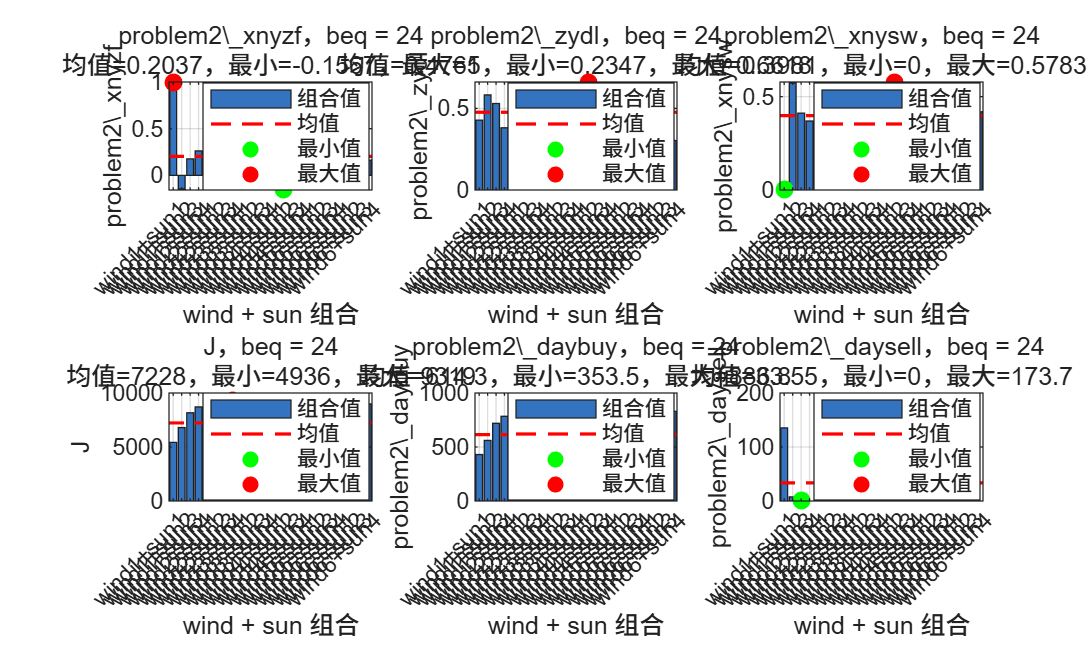

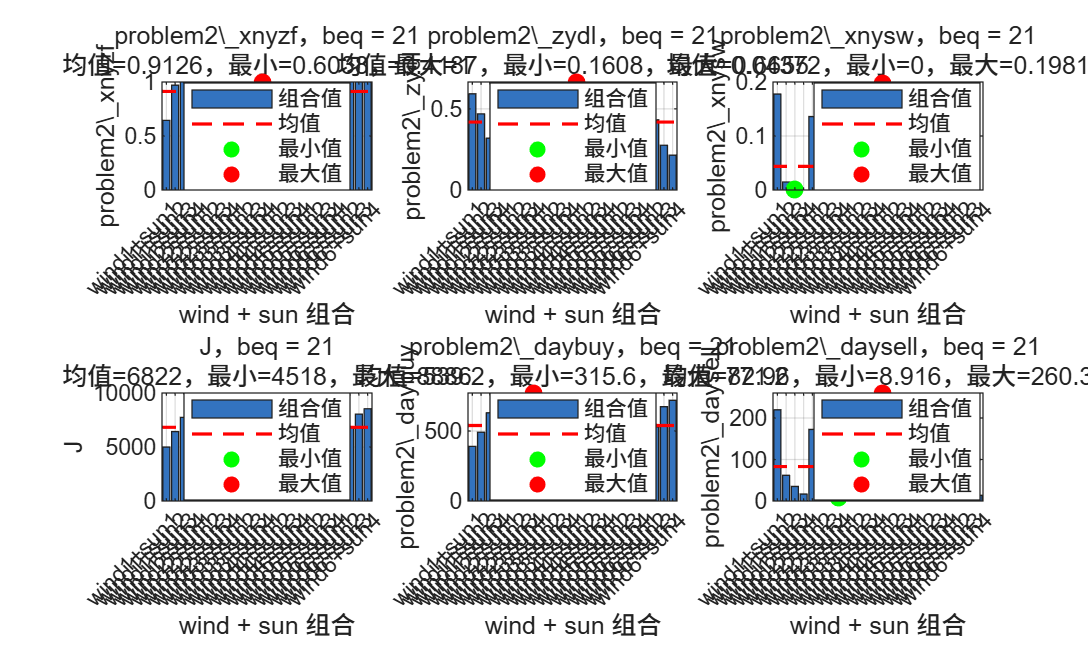

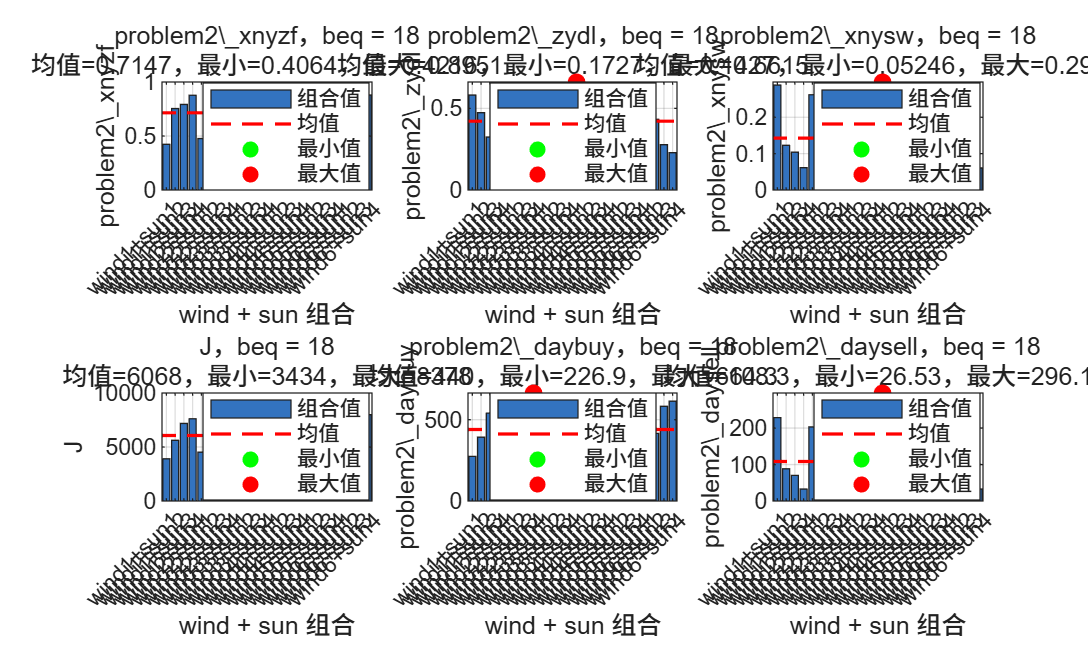

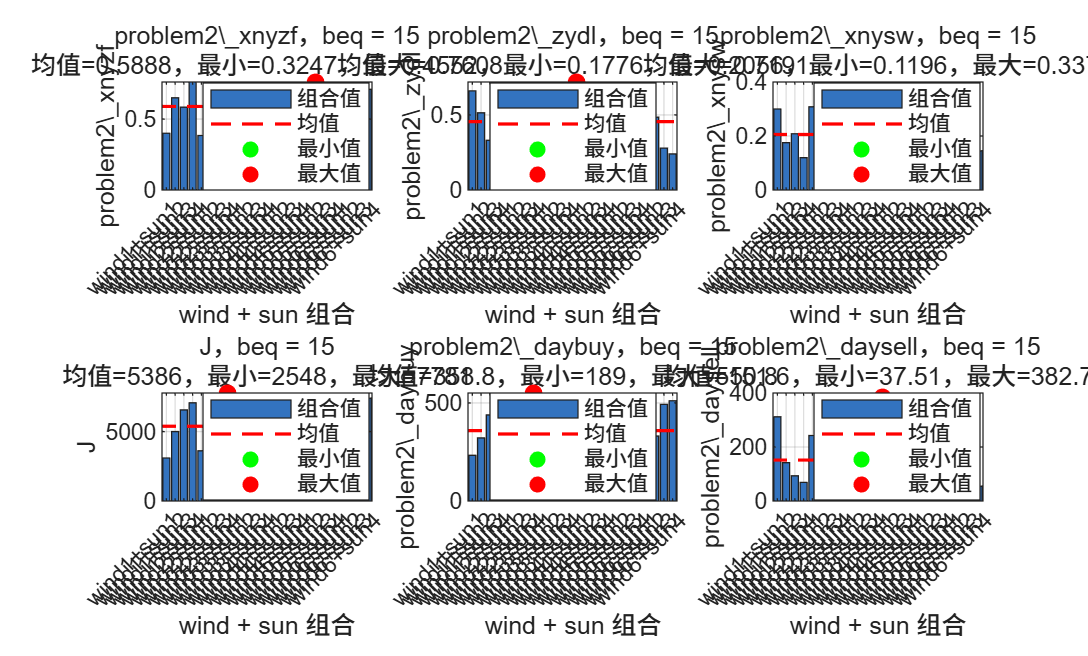

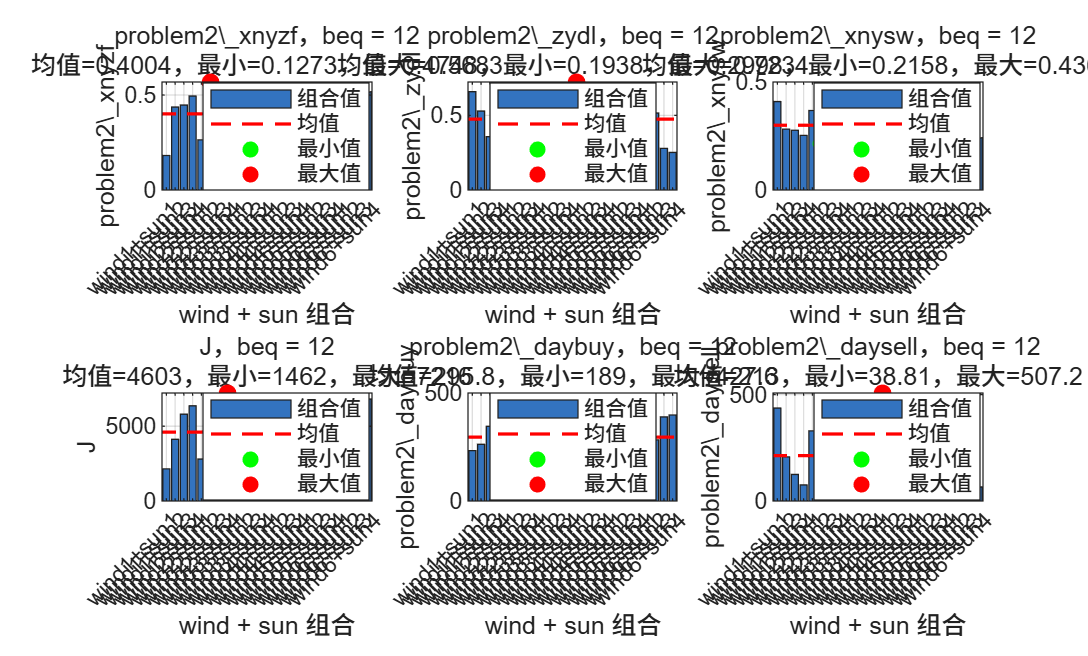


plotProblem2Distributions(problem2_results, beq_values);


function metrics = calcProblem2Metrics(t, classicload, wind, sun, fenshijijia, ...
                                       problem2_dayload, problem2_daysell, ...
                                       problem2_daybuy, problem2_daygenerate)
    t = t(:);
    classicload = classicload(:);
    wind = wind(:);
    sun = sun(:);
    fenshijijia = fenshijijia(:);

    metrics.nh3load = t*20.75*2;
    metrics.load = classicload*6 + metrics.nh3load;
    metrics.generate = wind*40 + sun*64;
    metrics.buy = metrics.load - metrics.generate;
    metrics.sell = metrics.buy;
    metrics.buy(metrics.buy<0) = 0;
    metrics.sell(metrics.sell>0) = 0;
    metrics.buycost = sum(metrics.buy .* fenshijijia);
    metrics.dayload = sum(metrics.load);
    metrics.daygenerate = sum(metrics.generate);
    metrics.daybuy = sum(metrics.buy);
    metrics.daysell = abs(sum(metrics.sell));

    % 保持原文件的指标计算方式
    metrics.xnyzf = (problem2_dayload-problem2_daysell-problem2_daybuy)/problem2_daygenerate;
    metrics.zydl = (problem2_daygenerate-problem2_daysell)/problem2_dayload;
    metrics.xnysw = problem2_daysell/problem2_daygenerate;
end


function plotProblem2Distributions(problem2_results, beq_values)
    metric_fields = {'xnyzf', 'zydl', 'xnysw', 'J_min', 'daybuy', 'daysell'};
    metric_names = {'problem2\_xnyzf', 'problem2\_zydl', 'problem2\_xnysw', ...
                    'J', 'problem2\_daybuy', 'problem2\_daysell'};

    for beq_idx = 1:numel(beq_values)
        beq = beq_values(beq_idx);
        beq_mask = [problem2_results.beq] == beq;
        beq_results = problem2_results(beq_mask);

        if isempty(beq_results)
            warning('beq = %g 没有可绘制的结果。', beq);
            continue;
        end

        sort_keys = [[beq_results.wind_idx]', [beq_results.sun_idx]'];
        [~, order] = sortrows(sort_keys, [1 2]);
        beq_results = beq_results(order);

        combo_labels = arrayfun(@(r) sprintf('%s+%s', r.wind_name, r.sun_name), ...
                                beq_results, 'UniformOutput', false);

        figure('Name', sprintf('beq=%g 下 24 种 wind/sun 组合指标分布', beq), ...
               'Color', 'w');

        for metric_idx = 1:numel(metric_fields)
            metric_field = metric_fields{metric_idx};
            metric_name = metric_names{metric_idx};
            values = arrayfun(@(r) r.(metric_field), beq_results);

            subplot(2, 3, metric_idx);
            bar(values, 'FaceColor', [0.2 0.45 0.75]);
            grid on;
            hold on;

            valid_values = values(~isnan(values));
            mean_value = mean(valid_values);
            min_value = min(valid_values);
            max_value = max(valid_values);
            [~, min_idx] = min(values);
            [~, max_idx] = max(values);

            plot(xlim, [mean_value mean_value], 'r--', 'LineWidth', 1.2);
            scatter(min_idx, min_value, 45, 'g', 'filled');
            scatter(max_idx, max_value, 45, 'r', 'filled');

            title({sprintf('%s，beq = %g', metric_name, beq), ...
                   sprintf('均值=%.4g，最小=%.4g，最大=%.4g', ...
                           mean_value, min_value, max_value)}, ...
                  'Interpreter', 'none');
            xlabel('wind + sun 组合');
            ylabel(metric_name, 'Interpreter', 'none');
            set(gca, 'XTick', 1:numel(combo_labels), ...
                     'XTickLabel', combo_labels, ...
                     'XTickLabelRotation', 45);
            xlim([0.5, numel(combo_labels) + 0.5]);

            if min_value == max_value
                ylim([min_value - 0.5, max_value + 0.5]);
            end

            legend({'组合值', '均值', '最小值', '最大值'}, ...
                   'Location', 'best', 'FontSize', 8);
            hold off;
        end
    end
end